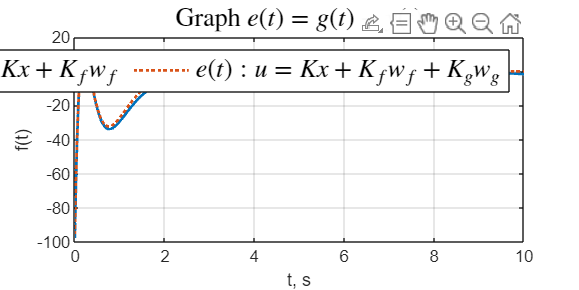

clear;
%=======Задающий сигнал======
G_g = [0 2 0;
    -2 0 0;
    0 0 0];
Y_g = [1 0 -2];
w_g0 = [1; 0; 1];

%======Система==========

A = [5 8 5; -6 -9 -8; 6 6 5];
B = [2; 0; 0];
C = [2 -3 -2];
Bf = [-3 1; 3 0; 0 0];
D = [7];
Df = [5 6];
x0 = [0; 0; 0];
%=====Внешнее возмущение====
G_f = [0 1 0 1;
    -26 -7 20 -11;
    0 1 -1 2;
    16 4 -14 8];
Y_f = [2 0 -2 1;
    -4 -2 4 -3];
w_f0 = [1; 1; 1; 1];

%====Синтез К========
%K = [-6.5 -0.25 0.25];

%====Синтез Кg========
%{
chek_g = [A+B*K-(0*eye(3)) B; C+D*K D];
disp('check_g');
disp(chek_g);
disp(rank(chek_g));


cvx_begin sdp

variable Pg(3, 3)
variable Kg(1, 3)
Pg*G_g-(A+B*K)*Pg==B*Kg;
(C+D*K)*Pg+D*Kg==Y_g;

cvx_end

disp('Pg');
disp(Pg);
disp('Kg');
disp(Kg);
%}

%Kg = [0.0468 0.2563 -0.3738];


%====Синтез Кf========
%{

chek_f = [A+B*K-(-2j*eye(3)) B; C+D*K D];
disp('check_f');
disp(chek_f);
disp(rank(chek_f));

cvx_begin sdp

variable Pf(3, 4)
variable Kf(1, 4)
Pf*G_f-(A+B*K)*Pf-Bf*Y_f==B*Kf;
(C+D*K)*Pf+D*Kf==-Df*Y_f;

cvx_end

disp('Pf');
disp(Pf);
disp('Kf');
disp(Kf);
%}

%Kf = [16.0012 6.4817 -11.3156 6.2353]


%K = [0 0 0];
%Kf = [0 0 0 0];
%Kg = [0 0 0];

t = linspace(0, 15, 2000);
open_system('task_1_sim');
set_param('task_1_sim/g_', 'VariableName', 'g_')
set_param('task_1_sim/f_', 'VariableName', 'f_')
set_param('task_1_sim/x', 'VariableName', 'x')
set_param('task_1_sim/y', 'VariableName', 'y')
set_param('task_1_sim/u', 'VariableName', 'u')
set_param('task_1_sim/e', 'VariableName', 'e')

%Kf = [0 0 0 0];
%Kg = [0 0 0];
%Kf = [16.0012 6.4817 -11.3156 6.2353];
%K = [-6.5 -0.25 0.25];
%Kg = [0.0468 0.2563 -0.3738];

%out = sim('task_1_sim');
%figure('Position', [100 100 800 400])
%{
plot(out.g_,'-', 'LineWidth',1.5);
%hold on
%plot(t, cos(2*t)-2,'--', 'LineWidth',1.5);

grid()
title('Graph $g(t)$','Interpreter','latex',  'FontSize', 14)
legend('$g(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
%hold off


plot(out.f_,'-', 'LineWidth',1.5);

grid()
title('Graph $f(t)$','Interpreter','latex',  'FontSize', 14)
legend('$f_1(t)$','$f_2(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
%}

%{
plot(out.x,'-', 'LineWidth',1.5);

grid()
title('Graph $x(t)$ for $u = Kx$','Interpreter','latex',  'FontSize', 14)
legend('$x_1(t)$','$x_2(t)$','$x_3(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
%}
%{
plot(out.y,'-', 'LineWidth',1.5);
grid()
title('Graph $y(t)$ for $u = 0$','Interpreter','latex',  'FontSize', 14)
legend('$y(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')


plot(out.u,'-', 'LineWidth',1.5);
grid()
title('Graph $u = 0$','Interpreter','latex',  'FontSize', 14)
legend('$u(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')

%}


Kf = [16.0012 6.4817 -11.3156 6.2353];
K = [-6.5 -0.25 0.25];
Kg = [0 0 0];

out = sim('task_1_sim');
figure('Position', [100 100 800 400])
plot(out.e,'-', 'LineWidth',1.5);
hold on

Kf = [16.0012 6.4817 -11.3156 6.2353];
K = [-6.5 -0.25 0.25];
Kg = [0.0468 0.2563 -0.3738];

out = sim('task_1_sim');
plot(out.e,':', 'LineWidth',1.5);



grid()
title('Graph $e(t) = g(t)-y(t)$','Interpreter','latex',  'FontSize', 14)
legend('$e(t):u = Kx+K_fw_f$' ,...
    '$e(t):u = Kx+K_fw_f+K_gw_g$','Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
%ylim([-40 30])
hold off


%{
K = [-6.5 -0.25 0.25];
Kf = [0 0 0 0];
Kg = [0 0 0];
out = sim('task_1_sim');

figure('Position', [100 100 800 400])
plot(out.u,'-', 'LineWidth',1.5);
hold on

Kf = [16.0012 6.4817 -11.3156 6.2353];
K = [-6.5 -0.25 0.25];
Kg = [0 0 0];

out = sim('task_1_sim');
plot(out.u,'-', 'LineWidth',1.5);

Kf = [0 0 0 0];
K = [-6.5 -0.25 0.25];
Kg = [0.0468 0.2563 -0.3738];

out = sim('task_1_sim');
plot(out.u,':', 'LineWidth',1.5);

Kf = [16.0012 6.4817 -11.3156 6.2353];
K = [-6.5 -0.25 0.25];
Kg = [0.0468 0.2563 -0.3738];

out = sim('task_1_sim');
plot(out.u,':', 'LineWidth',1.5);
hold on


grid()
title('Graph $u(t)$','Interpreter','latex',  'FontSize', 14)
legend('$u = Kx$', ...
    '$u = Kx+K_fw_f$', '$u = Kx+K_gw_g$' ,...
    '$u = Kx+K_fw_f+K_gw_g$','Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
ylim([-40 30])
hold off
%}

%{
K = [-6.5 -0.25 0.25];
Kf = [0 0 0 0];
Kg = [0 0 0];
out = sim('task_1_sim');

figure('Position', [100 100 800 400])
plot(out.y,'-', 'LineWidth',1.5);
hold on

Kf = [16.0012 6.4817 -11.3156 6.2353];
K = [-6.5 -0.25 0.25];
Kg = [0 0 0];

out = sim('task_1_sim');
plot(out.y,'-.', 'LineWidth',1.5);

Kf = [0 0 0 0];
K = [-6.5 -0.25 0.25];
Kg = [0.0468 0.2563 -0.3738];

out = sim('task_1_sim');
plot(out.y,':', 'LineWidth',1.5);

Kf = [16.0012 6.4817 -11.3156 6.2353];
K = [-6.5 -0.25 0.25];
Kg = [0.0468 0.2563 -0.3738];

out = sim('task_1_sim');
plot(out.y,':', 'LineWidth',1.5);
hold on


grid()
title('Graph $y(t)$','Interpreter','latex',  'FontSize', 14)
legend('$y(t): u = Kx$', ...
    '$y(t): u = Kx+K_fw_f$', '$y(t): u = Kx+K_gw_g$' ,...
    '$y(t): u = Kx+K_fw_f+K_gw_g$','Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')

hold off
%}